## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 02 - Structural Representation and Code Organization**

#### **2.5 Changing the code without going deep into the package!**

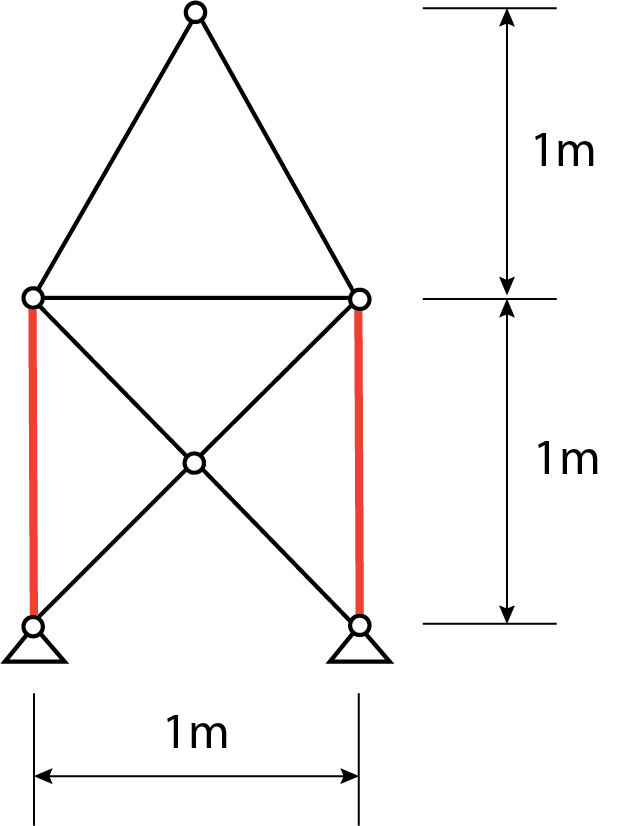

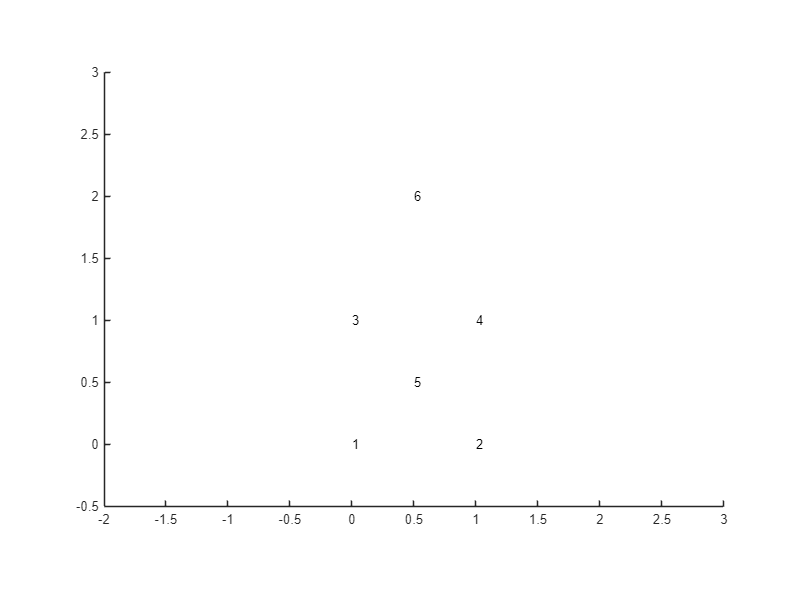

% Create the truss Assembly
assembly=Assembly_Truss;

% Define the node object
node=Elements_Nodes;

% Create the bar object
bar=Vec_Elements_Bars;
actBar=CD_Elements_Bars;

% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.actBar=actBar;

% Define the nodal coordinates
% Length of each span
L=1; 

% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0 0 0; 
                      L 0 0;
                      0 0 L;
                      L 0 L;
                      0.5*L 0 0.5*L;
                      0.5*L 0 2*L;
                      ];

% Set up the plotting function for inspection
plots=Plot_Truss();
plots.assembly=assembly;

% We will plot for the truss assembly
plots.displayRange=[-2;3;-1;1;-0.5;3]; 
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

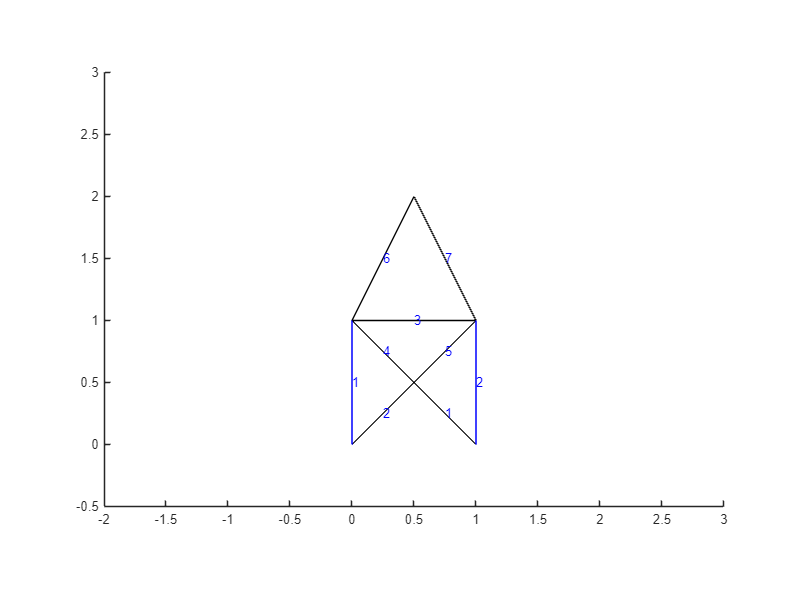

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[2,5;
                 1,5;
                 3,4;
                 3,5;
                 4,5;
                 3,6;
                 4,6;]; 

% Next we design the active truss
actBar.node_ij_mat=[1 3;
                    2 4;];

% Property of normal truss
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% Property of active truss
activeBarE=2*10^6;

% Define the normal bars
bar.A_vec=barA*ones(7,1);
bar.E_vec=barE*ones(7,1);

% Define the active bars
actBar.A_vec=barA*ones(2,1);
actBar.E_vec=activeBarE*ones(2,1);

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Plot the bars
plots.Plot_Shape_Bar_Number()


% Define the extension and contraction
deltaL=0.2;
% Set up the self actuation solver
nr=Solver_NR_TrussAction;
nr.assembly=assembly;

nr.supp=[1,1,1,1;
         2,1,1,1;
         3,0,1,0;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;];

% Set up the actuation
nr.targetL0=actBar.L0_vec;

% Find the extention
nr.targetL0(1)=nr.targetL0(1)-deltaL;
nr.targetL0(2)=nr.targetL0(2)+deltaL;

% Set up the total loading step
nr.increStep=10;
% Set up the maximum iteration
nr.iterMax=30;

% Solve for the deformation history
Uhis=nr.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 5.660250e+00 
	Iteration = 2, R = 6.104105e+02 
	Iteration = 3, R = 7.294046e-01 
	Iteration = 4, R = 1.070077e-04 
	Iteration = 5, R = 8.532337e-09 
Icrement = 2
	Iteration = 1, R = 5.669323e+00 
	Iteration = 2, R = 6.062672e+02 
	Iteration = 3, R = 7.196223e-01 
	Iteration = 4, R = 1.648914e-03 
	Iteration = 5, R = 1.481717e-07 
Icrement = 3
	Iteration = 1, R = 5.683009e+00 
	Iteration = 2, R = 5.823378e+02 
	Iteration = 3, R = 6.689670e-01 
	Iteration = 4, R = 1.464602e-01 
	Iteration = 5, R = 7.694499e-06 
Icrement = 4
	Iteration = 1, R = 5.701431e+00 
	Iteration = 2, R = 6.211876e+02 
	Iteration = 3, R = 7.610043e-01 
	Iteration = 4, R = 1.836013e-01 
	Iteration = 5, R = 2.276776e-05 
	Iteration = 6, R = 2.175760e-10 
Icrement = 5
	Iteration = 1, R = 5.724777e+00 
	Iteration = 2, R = 6.168166e+02 
	Iteration = 3, R = 7.531386e-01 
	Iteration = 4, R = 2.648919e-01 
	Iteration = 5, R = 1.060279e-05 
	Iteration = 6, R = 8.3

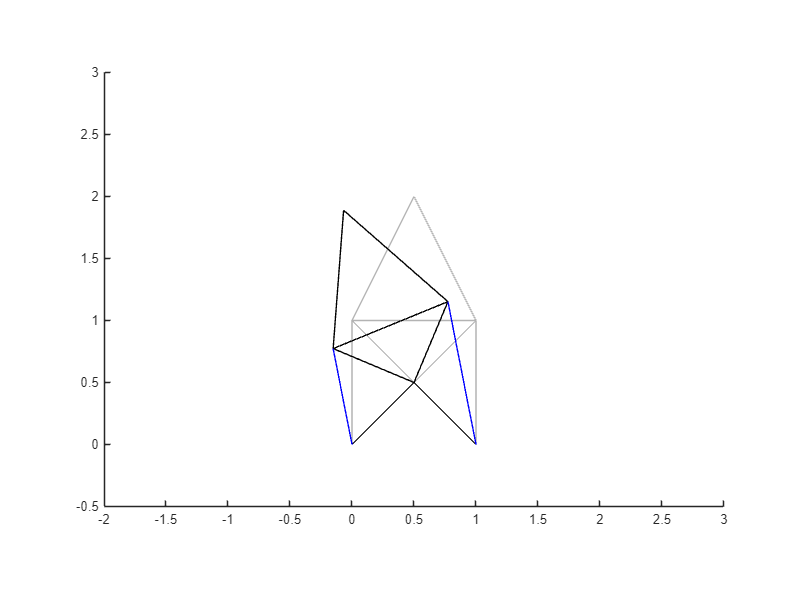

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));